Calculates EOD amplitude statistics for the Brasil *Eigenmannia* data.

The values are in **Ampere-meters**.

This is **FIGURE 3B** of the Cave Manuscript.

% Data are found in these files - load them before running this script
% load CaveDataRev2018a.mat
% load SurfaceDataRev2018a.mat

## Setup


% Set the number of bins for the histogram here:

    numbins = 20;
    
    ctrs = 0:0.003/numbins:0.003;
    
% There are Contaminated / Bad amplitude readings in surface data
% srf(1).fish(12), srf(2).fish(20), srf(3).fish(31), 
% srf(4).fish(22), srf(5).fish(4), srf(5).fish(23)

BadIDXs = [12,32,64,86,90,109];


## Extract the electric field strength values for the fish


CaveAmps = []; SurfaceAmps = []; 

for j=1:length(srf) 
    for k=1:length(srf(j).fish) 
        SurfaceAmps(end+1) = srf(j).fish(k).dipStrength; 
    end
end

for j=1:length(cave)
    for k=1:length(cave(j).fish)
        CaveAmps(end+1) = cave(j).fish(k).dipStrength; 
    end
end

GoodIDXs = setdiff(1:length(SurfaceAmps), BadIDXs);


## Calculate the statistics for surface and cavefish

    stts.meanSurfaceAmp = mean(SurfaceAmps(GoodIDXs));
    stts.meanCaveAmp = mean(CaveAmps);
    stts.stdSurfaceAmp = std(SurfaceAmps(GoodIDXs));
    stts.stdCaveAmp = std(CaveAmps);    
    
[stts.H, stts.P, stts.CI, stts.STATS] = ttest2(CaveAmps, SurfaceAmps(GoodIDXs), 'vartype', 'unequal');

    fprintf('ttest2 cave and surface? pVal = %1.5f, CI = %1.5f %1.5f \n', stts.P, stts.CI(1), stts.CI(2));

ttest2 cave and surface? pVal = 0.01167, CI = 0.00007 0.00056 


    stts.STATS

ans = struct with fields:
    tstat: 2.5523
       df: 155.0195
       sd: [9.0745e-04 7.4193e-04]


    fprintf('Cave mean & std ampere-centimeters %1.6f %1.6f \n', stts.meanCaveAmp, stts.stdCaveAmp);

Cave mean & std ampere-centimeters 0.000966 0.000907 


    fprintf('Surface mean & std ampere-centimeters %1.6f %1.6f \n', stts.meanSurfaceAmp, stts.stdSurfaceAmp);    

Surface mean & std ampere-centimeters 0.000650 0.000742 


## Plot the amplitude data for the manuscript

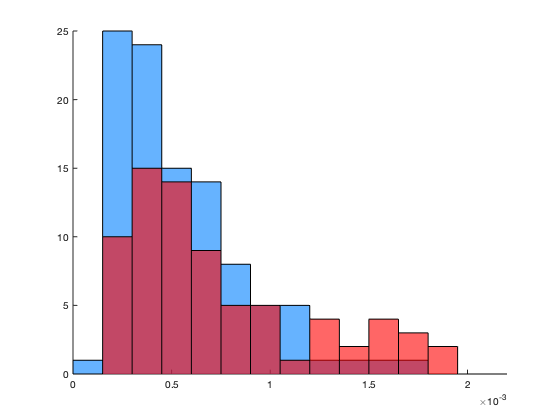

    
% figure(1); clf; hold on;
%     histogram(SurfaceAmps(GoodIDXs), ctrs, 'FaceColor', '[0 0.5 1]');
%     histogram(CaveAmps, ctrs, 'FaceColor', '[1 0 0]'); 
%     xlim([0 0.0022]);

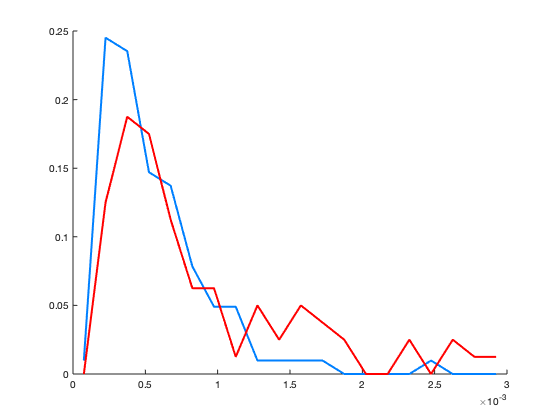

% 
% figure(2); clf; hold on;
%     surfhist = histcounts(SurfaceAmps(GoodIDXs), ctrs);
%         surfhist = surfhist / sum(surfhist);
%     cavehist = histcounts(CaveAmps, ctrs);
%         cavehist = cavehist / sum(cavehist);
        
    plotspots = ctrs(2:end) - 0.003/(2*numbins);
    % plot(plotspots, surfhist, 'Color', '[0 0.5 1]', "LineWidth", 2);
    % plot(plotspots, cavehist, 'Color', '[1 0 0]', "LineWidth", 2);

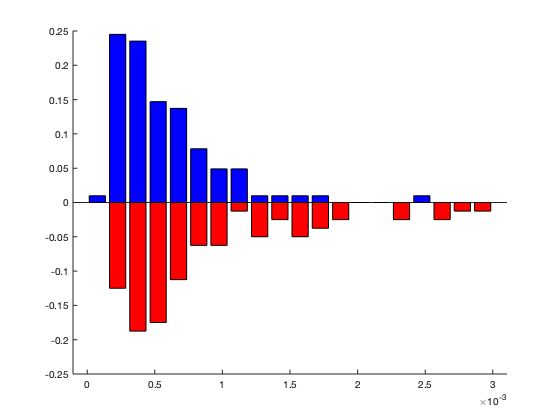

    
figure(3); clf; hold on;
    bar(plotspots, surfhist, 'b');
    bar(plotspots, -cavehist, 'r');
    ylim([-0.25, 0.25]);

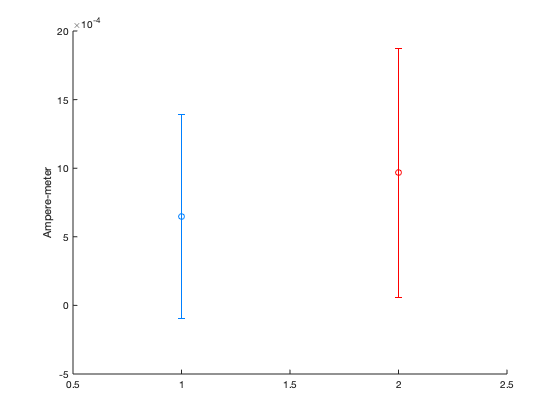

    
figure(4); clf; hold on;
    plot(1,stts.meanSurfaceAmp, 'o', 'Color', '[0 0.5 1]');
        errorbar(1, stts.meanSurfaceAmp, stts.stdSurfaceAmp, "both", 'Color', '[0 0.5 1]')
    plot(2,stts.meanCaveAmp, 'o', 'Color', '[1 0 0]')
        errorbar(2, stts.meanCaveAmp, stts.stdCaveAmp, "both", 'Color', '[1 0 0]')
    xlim([0.5 2.5])
    ylabel('Ampere-meter');